# Compare solar panel production to theory

This script implements a simple model of solar electricity production for the solar array on the "Apple Hill 3" building at MathWorks headquarters in Natick, Massachusetts. This model is compared to the recorded data for a single clear day close to the summer solstice, which makes it a good approximation of the maximum possible daily production.

See the [*Getting Started with MATLAB* video](https://www.mathworks.com/support/learn-with-matlab-tutorials.html) for details.

Copyright 2019 The MathWorks, Inc.

## Theoretical power production

Define declination of the sun and latitude of the solar panels.

Declination is the angle of the sun from the equator:

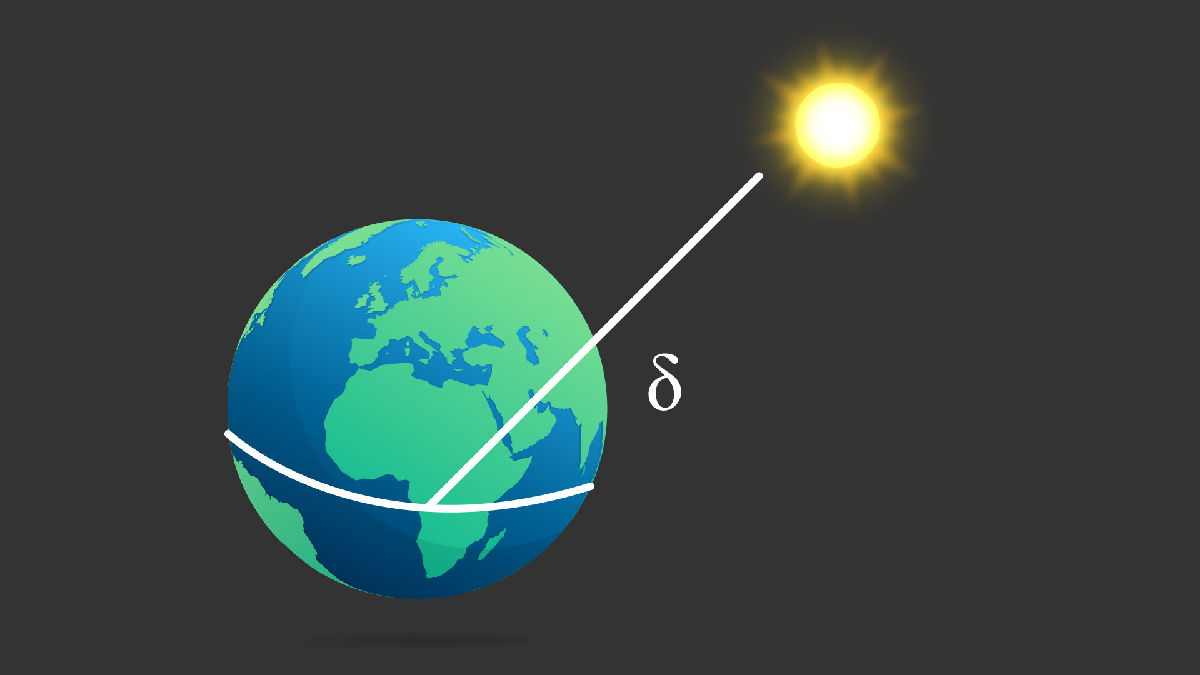

It depends on the time of year.

dec = 23.45       % Summer solstice

dec = 23.4500

lat = 42 + 17/60  % Natick: 42° 17'

lat = 42.2833

Convert from degrees to radians

dec = deg2rad(dec);
lat = deg2rad(lat);

Make a vector of times from 5:30 am to 8 pm (slightly after sunrise to slightly before sunset). Use 1/4-hour increments (to match measured data).

t = 5.5:0.25:20;

Calculate local solar time. Solar panel longitude is 71° 21' W. EST median longitude is 75°. Time correction is therefore 4*(75-71.35) = 14.6 minutes. Also adjust for daylight savings.

LST = t - 1 + 14.6/60;

Determine the amount of solar irradiance on the solar panels:

$S_{panel} = S_{incident} \sin(\alpha)$, where $S_{incident} = 1.4883 \times 0.7^{\sin(\alpha)^{-0.678}}$ and $\alpha$ is the elevation of the sun, given by

$\sin(\alpha) = \sin(\delta)\sin(\phi) + \cos(\delta)\cos(\phi)\cos(15^\circ(LST - 12))$, where $\delta$ is the declination of the sun and $\phi$ is the latitude.

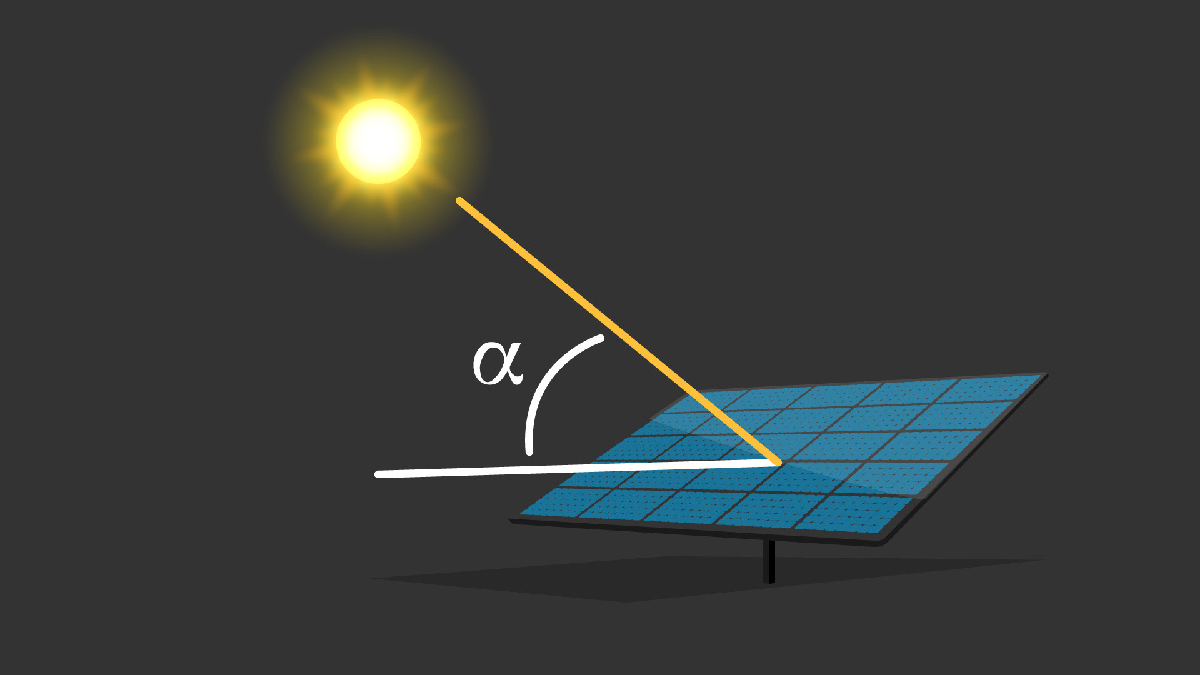

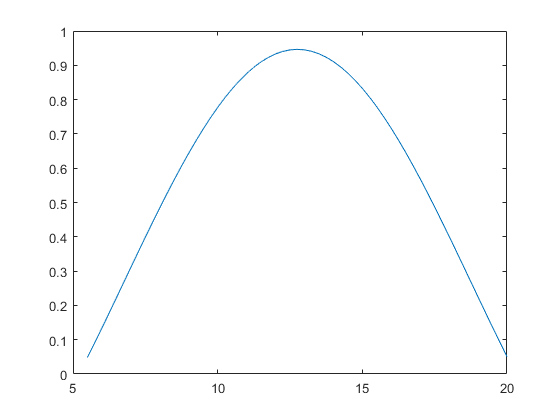

sunangle = sin(dec)*sin(lat) + cos(dec)*cos(lat)*cosd(15*(LST - 12));
plot(t,sunangle)

$S_{incident}$ is an empirical formula that models the reduction in incident energy due to the atmosphere - the more air the sunlight has to pass through, the more energy is lost:

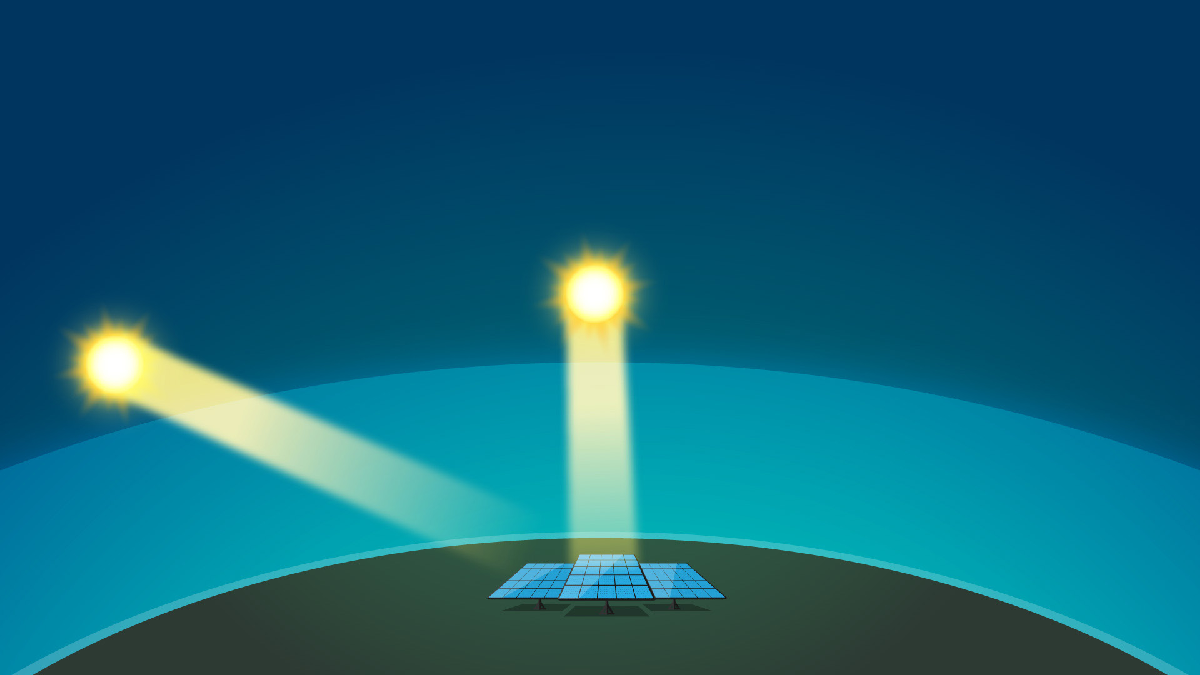

S_inc = 1.4883*0.7.^(sunangle.^-0.678);

Calculate the final theoretical production for the whole array of panels, including the inverter limit (207 kW).

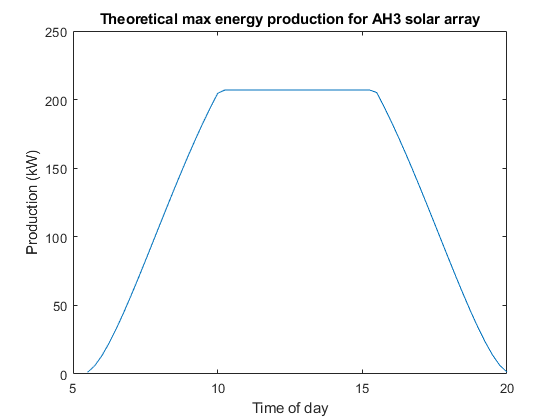

production_theory = 270*S_inc.*sunangle;
production_theory = min(production_theory,207);
plot(t,production_theory)
xlabel('Time of day')
ylabel('Production (kW)')
title('Theoretical max energy production for AH3 solar array')

## Compare with recorded data

Import data for June 2018 from file.

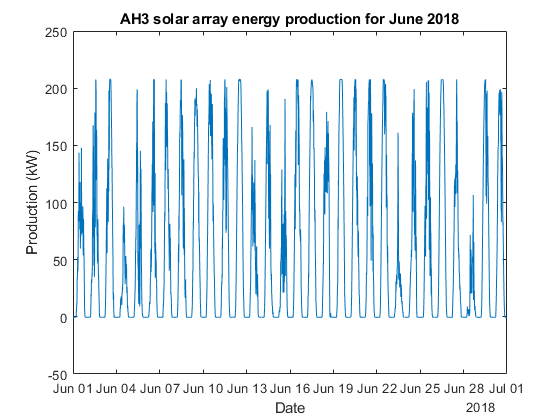

production = readtable("SolarArrayProduction.xlsx");  % equivalent to using the Import Tool
plot(production.Timestamp,production.AH3)
xlabel('Date')
ylabel('Production (kW)')
title('AH3 solar array energy production for June 2018')

Zoom in on June 21 (summer solstice).

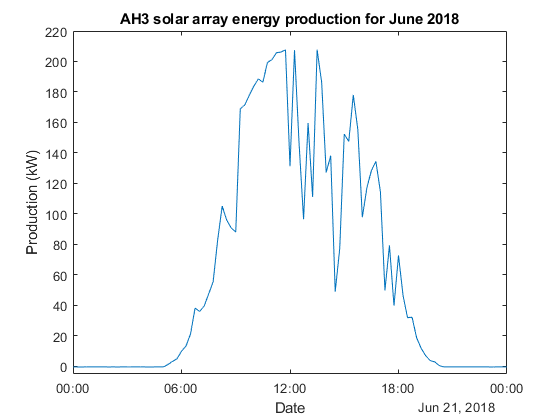

xlim(datetime(2018,6,21:22))
ylim([-5 220])

Zoom in on June 26 (completely clear day).

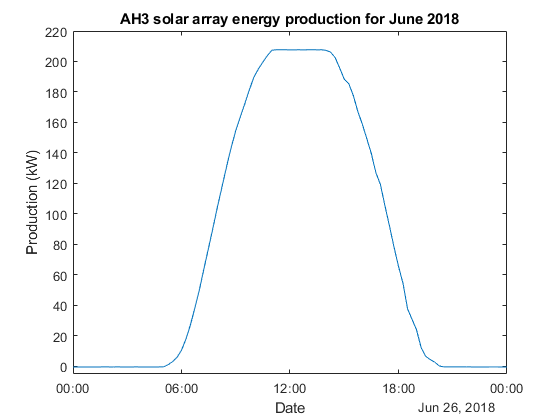

xlim(datetime(2018,6,26:27))
ylim([-5 220])

Reorganize data into a matrix of times by days (4*24 = 96 times, by 30 days).

June2018 = reshape(production.AH3,96,30);

Extract a specific day (June 26 because it is close to the solstice and completely clear).

dayofinterest = June2018(:,26);

Make a vector of times and plot the data for one day.

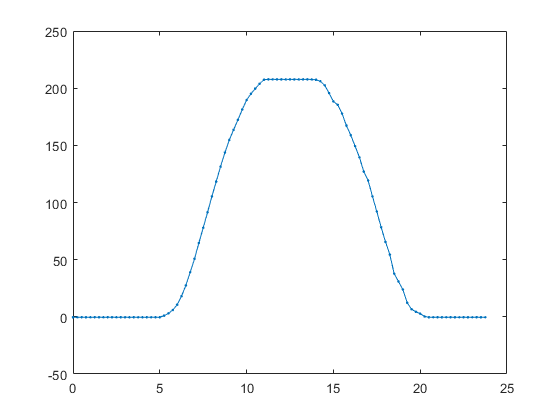

tfullday = 0:0.25:23.75;
plot(tfullday,dayofinterest,'.-')

Compare against theory.

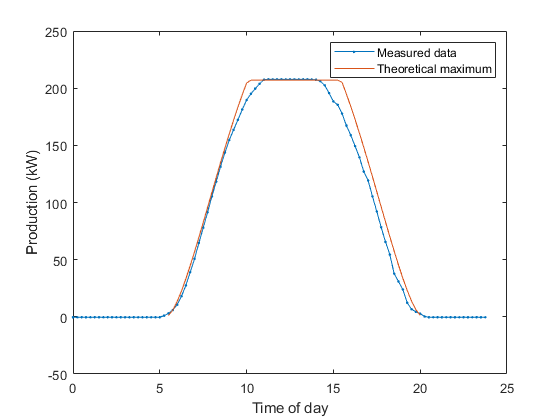

plot(tfullday,dayofinterest,'.-',t,production_theory)
xlabel('Time of day')
ylabel('Production (kW)')
legend('Measured data','Theoretical maximum')